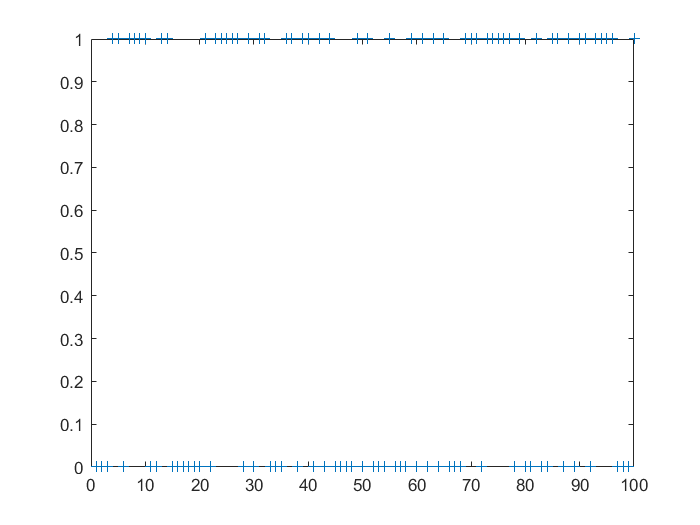

L=100;
d=floor(rand(1,L)*2); %产生长为L个符号的{0,1}二元符号串
figure; plot(d,'+');

x=(1-d*2)*(1+sqrt(-1)); %将序列d映射到一个复数符号流，d中每个二元符号映射到一个复电平，0映射到1+j，1映射到-1-j，每符号能量为2
figure; plot(x,'ro');
mean_signal_energy_per_symbol = x*x'/length(x) %测量显示一下x的平均每符号能量，

mean_signal_energy_per_symbol = 2

n=(randn(1,L)+sqrt(-1)*randn(1,L))/sqrt(2); %实虚部方差均为1/2，总方差为1的零均值复高斯噪声序列
mean_noise_energy_per_symbol = n*n'/length(n) %测量验证一下n的平均每符号能量

mean_noise_energy_per_symbol = 0.9202

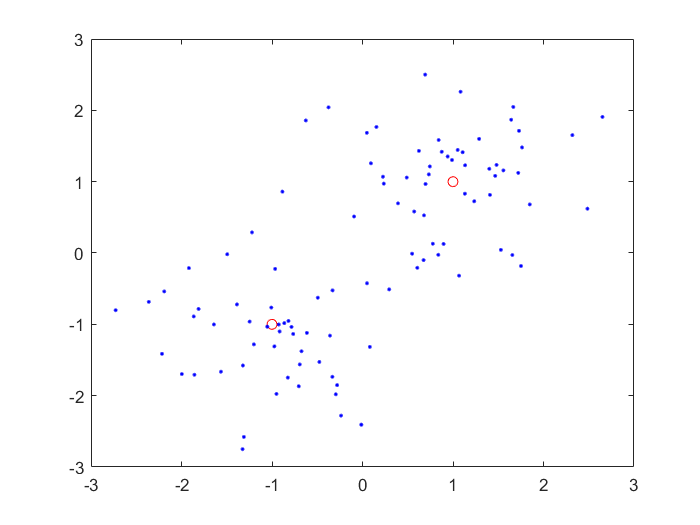

y=x+n*sqrt(1.1);  %将x通过一个平均每符号噪声能量为1.1的加性复高斯噪声电平信道，输出复电平序列y
hold on; plot(y,'b.')

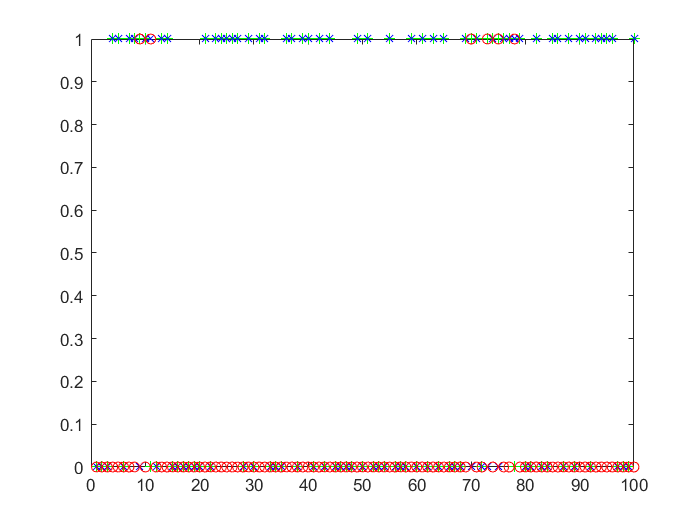

decision=round((1-sign(real(y)))/2); %采取一定的方式，对接收到的信道输出复电平序列，逐符号进行判决，得到关于发送序列的一个估计（可能有误）,round的目的是为了避免sgn函数输出为0影响的影响
error_pattern=abs(decision-d);
figure;plot(d,'g+'); hold on; plot(decision,'bx'); plot(error_pattern,'ro');

error_num=sum(sign(error_pattern));
BER=error_num/length(d)

BER = 0.0600

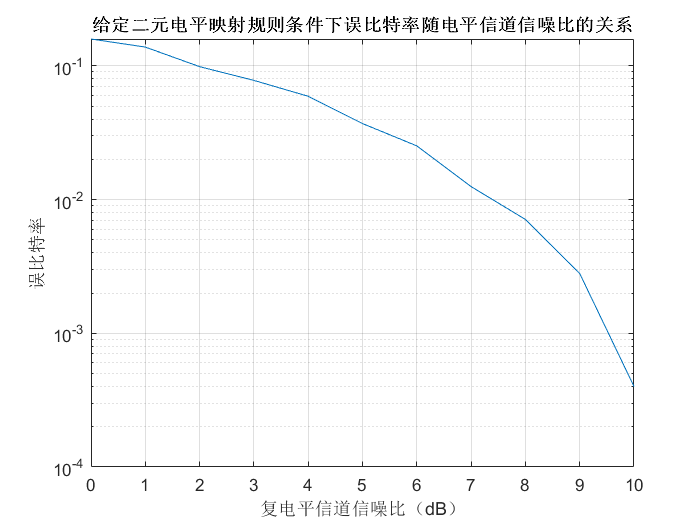



%前面的代码是示范一下，一次简单的复电平采样序列的传输，判决，以及误码统计

%后面的代码是，尝试不同的复电平信道信噪比，画出误码率随信道SNR的关系曲线
%注意，这里每个信噪比条件下，只仿真了一次电平序列（共L个采样或电平），
%在我们的作业里，如果要仿真变化的信道，每次的电平序列不一定要太长，但要有足够多次数，即多次不同的电平序列传输，再求平均误码率
snr_dB=0:1:10;
L=10000;
BER=snr_dB*0;
for i=1:length(snr_dB)
    d=floor(rand(1,L)*2); %产生长为L个符号的{0,1}二元符号串
    d=d*0;
    x=(1-d*2)*(1+sqrt(-1)); %将序列d映射到一个复数符号流，d中每个二元符号映射到一个复电平，0映射到1+j，1映射到-1-j，平均符号能量为2
    noise_power = 2 / (10^(snr_dB(i)/10)); % 计算当前SNR时所对应的信道噪声符号平均能量，
    n=(randn(1,L)+sqrt(-1)*randn(1,L))/sqrt(2)*sqrt(noise_power); %产生对应噪声功率的噪声序列
    y=x+n;  %将x通过一个平均每符号噪声能量为noise_power的加性复高斯噪声电平信道，输出复电平序列y
    decision=round((1-sign(real(y)))/2); %采取一定的方式，对接收到的信道输出复电平序列，逐符号进行判决，得到关于发送序列的一个估计（可能有误）,round的目的是为了避免sgn函数输出为0影响的影响
% 注意，上面的判决方式不一定是最好的，大家可以思考一下，试一下，还有没有更好的判决方式，
    error_pattern=abs(decision-d);
    error_num=sum(sign(error_pattern));
    BER(i)=error_num/length(d);
end
figure;semilogy(snr_dB,BER);
xlabel('复电平信道信噪比（dB）');
ylabel('误比特率');
title('给定二元电平映射规则条件下误比特率随电平信道信噪比的关系')
grid